# Investigating Ergometer Strokes with Frequency Analysis

Karina Lamoreux & Brooke Moss

## Setup

The data we analyzed was gathered via two phones running MATLAB Mobile, both collecting accelerometer and orientation data. We attached one of these phones to the erg seat and one to the erg handle.

clear;
% Loads handle and seat acceleration and orientation data.
handle = load("initial_data\initial_handle.mat");
seat = load("initial_data\initial_seat.mat");

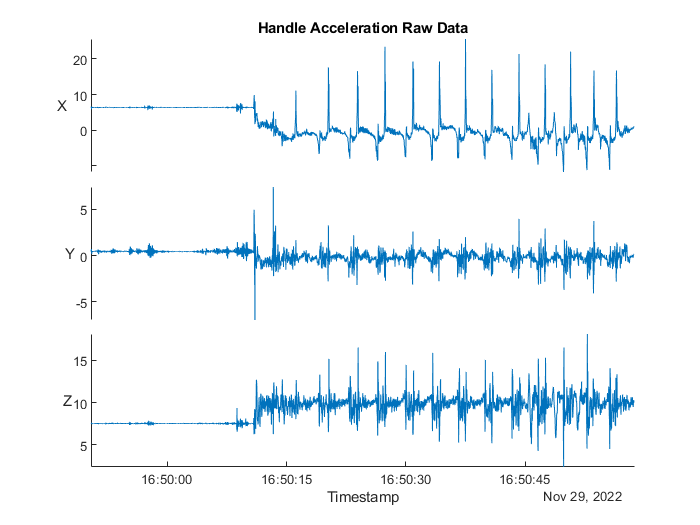

% Plots raw data received from sensors
clf;
stackedplot(handle.Acceleration);
title("Handle Acceleration Raw Data");

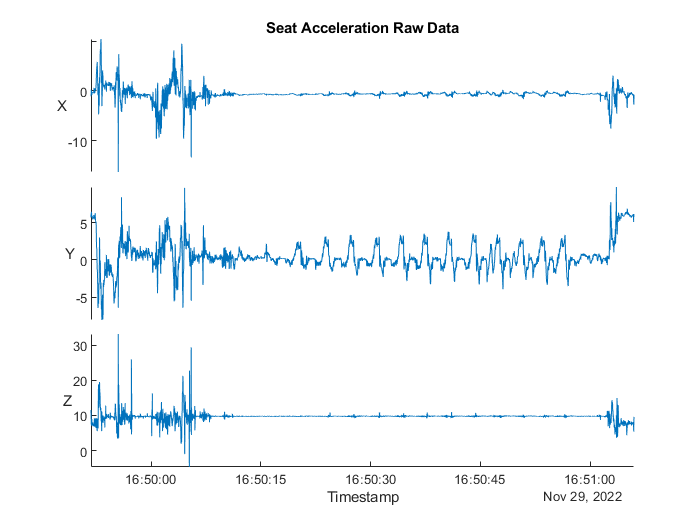


clf;
stackedplot(seat.Acceleration);
title("Seat Acceleration Raw Data");

Looking at the orientation data, it looked like our phones stayed perpendicular to the floor for the entire duration. We had initially planned to rotate the data so we could see the acceleration in only the axis in the direction of motion. After some testing, we found that this was unnecessary and the data was already pretty well aligned with the axis of motion. As you can see in the graph, there was some vibration in the other two axes but for our analysis, this was negligible. From the orientation of the phones, the x axis was parallel to the motion for the handle data, and the y axis was parallel for the seat. For our analysis, we used these data sets. 

During the test, multiple good strokes and multiple poorly-timed strokes were taken, as a way to compare. Here, we trim the data into two distinct tests so that we can compare the plot shapes for good and bad strokes.

% Defines time ranges of clean data for good and bad erg strokes.
good_range = timerange('29-Nov-2022 16:50:20.008','29-Nov-2022 16:50:35.719','closed');
bad_range = timerange('29-Nov-2022 16:50:44.103','29-Nov-2022 16:50:54.863','closed');

% Trims acceleration data into defined ranges.
handle.Acceleration_Good = handle.Acceleration(good_range, :);
seat.Acceleration_Good = seat.Acceleration(good_range, :);
handle.Acceleration_Bad = handle.Acceleration(bad_range, :);
seat.Acceleration_Bad = seat.Acceleration(bad_range, :);

## Velocity

To create velocity data to analyze and plot, we integrated the acceleration data.

% Integrates acceleration data to create sets of velocity data.
handle.Velocity_Good = timetable(handle.Acceleration_Good.Timestamp, cumtrapz(handle.Acceleration_Good.X), 'VariableNames',{'Handle'});
seat.Velocity_Good = timetable(seat.Acceleration_Good.Timestamp, cumtrapz(seat.Acceleration_Good.Y), 'VariableNames',{'Seat'});

handle.Velocity_Bad = timetable(handle.Acceleration_Bad.Timestamp, cumtrapz(handle.Acceleration_Bad.X), 'VariableNames',{'Handle'});
seat.Velocity_Bad = timetable(seat.Acceleration_Bad.Timestamp, cumtrapz(seat.Acceleration_Bad.Y), 'VariableNames',{'Seat'});

We then merged the handle and seat data sets, syncing them and interpolating their sample rates.

% Synchronizes and interpolates handle and seat timetables to create one merged dataset.
velocity_sync_good = synchronize(handle.Velocity_Good, seat.Velocity_Good, 'union', 'linear');
velocity_sync_bad = synchronize(handle.Velocity_Bad, seat.Velocity_Bad, 'union', 'linear');

## Normalization

Because our data was organized in timetable format, where the times were of a datetime type, we converted our time columns into vectors of elapsed time in seconds since the beginning of the test.

% Converts datetime from timetables into an elapsed time vector in seconds.
normal_time_good = velocity_sync_good.Time.Second - velocity_sync_good.Time.Second(1,:);
normal_time_bad = velocity_sync_bad.Time.Second - velocity_sync_bad.Time.Second(1,:);

Since the creep in our integrated data was very significant, we hard-coded a set of linear functions to subtract from each data set in order to get the data to sit flat period to period.

% Normalizes each dataset based on a hard-coded slope value to negate the effects of 
%   creep in the data (introduced as a result of the integration process).
normal_seat_good = velocity_sync_good.Seat - (153.347/12.377)*normal_time_good;
normal_handle_good = velocity_sync_good.Handle - (-275.964/7.127)*normal_time_good;

normal_seat_bad = velocity_sync_bad.Seat - (67.1946/7.75)*normal_time_bad;
normal_handle_bad = velocity_sync_bad.Handle - (-499.118/6.488)*normal_time_bad;

This plot is a demo of the normalized vs. raw velocity data.

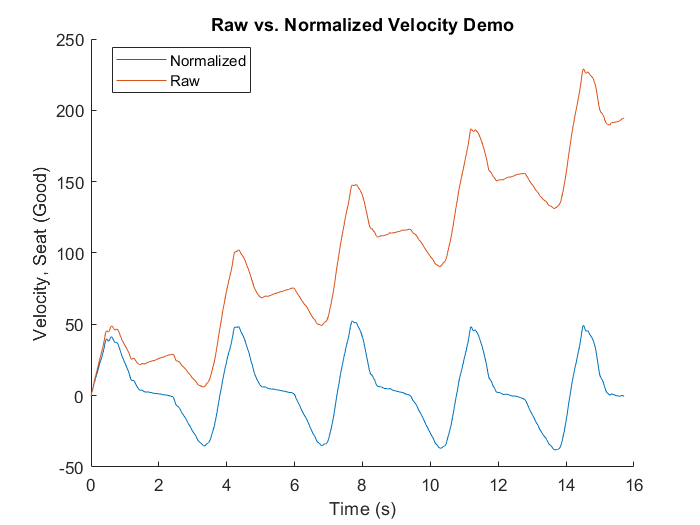

clf;
figure(1)
hold on;
plot(normal_time_good, normal_seat_good, normal_time_good, velocity_sync_good.Seat)
title('Raw vs. Normalized Velocity Demo')
xlabel('Time (s)')
ylabel('Velocity, Seat (Good)')
legend('Normalized', 'Raw', 'Location',"best")
hold off;

Once we have normalized the time and velocity, we combine them all together into arrays for plotting.

% Combines normalized time and velocity vectors into a good and bad array.
velo_normal_good = [normal_time_good normal_seat_good normal_handle_good];
velo_normal_bad = [normal_time_bad normal_seat_bad normal_handle_bad];

## Plotting

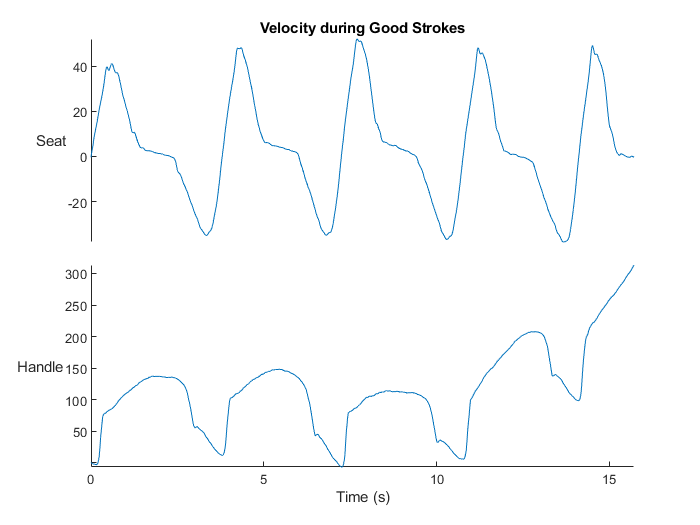

% Plots both good and bad velocity arrays, with seat and handle data side by side.
figure(2);
stackedplot(velo_normal_good(:,1), velo_normal_good(:,2:3), 'XLabel','Time (s)', 'DisplayLabels', {'Seat', 'Handle'})
title('Velocity during Good Strokes')

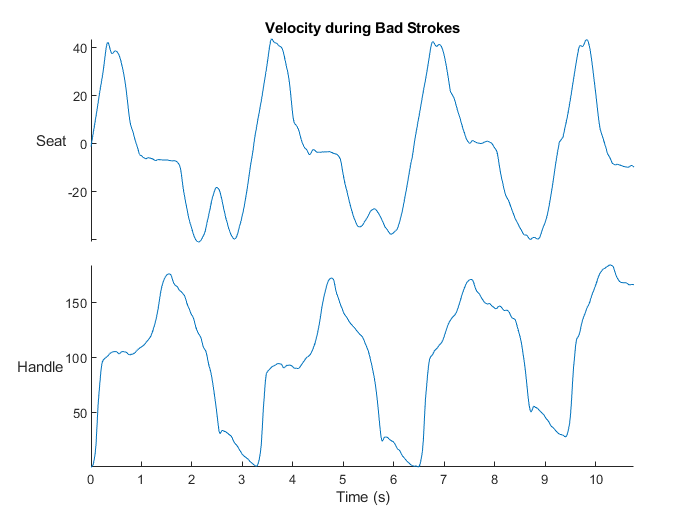


figure(3);
stackedplot(velo_normal_bad(:,1), velo_normal_bad(:,2:3), 'XLabel','Time (s)', 'DisplayLabels', {'Seat', 'Handle'})
title('Velocity during Bad Strokes')

## DFT

After plotting the velocity of the good and bad sections of the data, we wanted to see if the changes in the velocity plots between the good strokes and bad strokes can be seen in the DFT. To do this, we took the DFT of the normalized velocity for the both the seat and handle data to compare the frequencies found in the good and bad sections. We initially tried to plot the raw (non-normalized) data, but this data produced DFTs that were much less clear. 

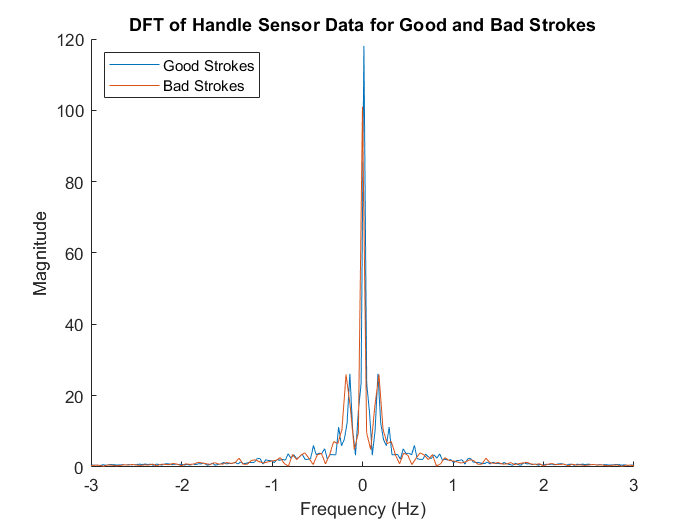

% defines the sampling frequency and finds the length of the sample
fs = 50;

% finds the DFT from each of the four data sets
dft_handle_good = fftshift(abs(fft(normal_handle_good)));
dft_handle_bad = fftshift(abs(fft(normal_handle_bad)));
dft_seat_good = fftshift(abs(fft(normal_seat_good)));
dft_seat_bad = fftshift(abs(fft(normal_seat_bad)));

% creates frequency plot comparing the DFT of good strokes and bad strokes for the handle sensor data
clf; hold on;
plot(linspace(-fs/2, fs/2, length(normal_handle_good)), dft_handle_good/length(normal_handle_good));
plot(linspace(-fs/2, fs/2, length(normal_handle_bad)), dft_handle_bad/length(normal_handle_bad));

title('DFT of Handle Sensor Data for Good and Bad Strokes');
xlabel('Frequency (Hz)'); ylabel('Magnitude');
legend('Good Strokes', 'Bad Strokes', 'Location', 'NW');
xlim([-3 3]);

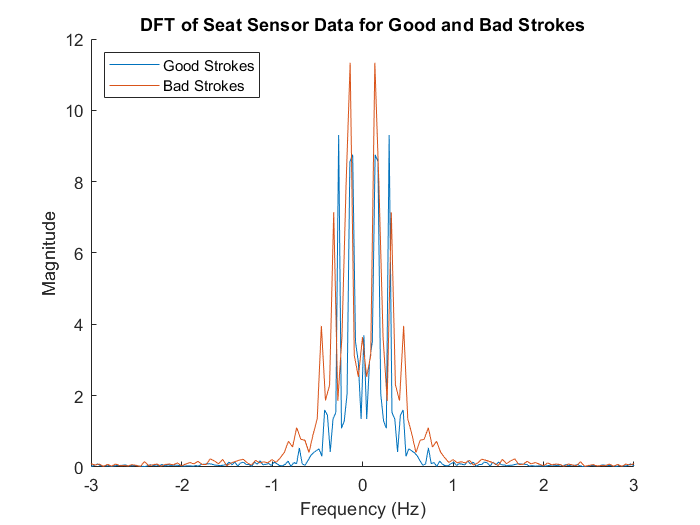


% creates frequency plot comparing the DFT of good strokes and bad strokes for the seat sensor data
clf; hold on;
plot(linspace(-fs/2, fs/2, length(normal_seat_good)), dft_seat_good/length(normal_seat_good));
plot(linspace(-fs/2, fs/2, length(normal_seat_bad)), dft_seat_bad/length(normal_seat_bad));

title('DFT of Seat Sensor Data for Good and Bad Strokes');
xlabel('Frequency (Hz)'); ylabel('Magnitude');
legend('Good Strokes', 'Bad Strokes', 'Location', 'NW');
xlim([-3 3]);